# Deterministic Simulations a Baby DICE model

This live script implements the solution of a non stationary climate-economic model using Dynare’s extended-path algorithm. The objective is to simulate the transition dynamics of a simplified Integrated Assessment Model (IAM).

## I. Initialization of the path of the model

### A. Preloading the model file

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.4).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Found 19 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the static model... 
10 block(s) found: 
  9 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 7 feedback variable(s). 
Computing dynamic model derivatives (order 2). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
3 block(s) found: 
  2 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 7 equation(s) 
                                 and 4 feedback variable(s). 
Preprocessing completed


STEADY-STATE RESULTS:

Z       		 23.3662
L       		 10.48
gZ      		 0
SIG     		 0
THETA1  		 0
delthet 		 0
M       		 2790.93
y       		 0.957955
c       		 0.957955
r       		 1.00503
w       		 0.93576
h       		 1.02372
mu      		 0
d       		 0.93576
tau     		 0
E       		 0
T       		 6.41914
tau_USD 		 0
s_a     		 1
Total computing time : 0h00m01s
Note: 1 warning(s) encountered in the preprocessor
Note: warning(s) encountered in MATLAB/Octave code


This step performs several essential tasks that prepare the environment for solving the full non stationary transition of the economy:

- Dynare reads the model equations and constructs all internal objects describing variables, parameters, shocks, and equilibrium conditions.

- The Jacobian and auxiliary derivative routines required for the extended path  algorithm are generated automatically. These routines are later used to solve the nonlinear system that characterizes the transition path.

- Dynare computes the steady state of the model or, when provided, calls the user defined `steady_state_model` block. This gives the long run values against which the transition is anchored.

- It also loads the initial state of the model as defined in the `endval` block, which represents the calibrated starting point of the economy.

After this step, the full numerical structure of the model is available in the workspace through the objects `M_`, `options_`, and `oo_`. These contain everything needed to compute the deterministic and stochastic non stationary paths of the economy using the extended path routines that we will call next.

### B. Summary of the extended-path setup

Before running the deterministic or stochastic transition, it is useful to inspect the configuration of the extended-path solver. The helper function `summarize_EP_setup` reports the start date, simulation horizon, expectation window, and the classification of shocks into surprise and expected components. This provides a quick diagnostic check that the model environment is correctly initialized after running the Dynare file.

% Summarize the extended-path environment
summarize_EP_setup(M_, options_);


=== Extended-path ===
Start date              : 1984Q4
Forward path horizon T  : 3000
Expectation window S    : 100
Terminal date           : 2734Q4

Surprise shocks (unanticipated):
  - e_a

Expected shocks (anticipated):
  - e_tau



The model contains two state variables that do not have analytical steady state expressions: the** long run stock of productivity A** and the **long run stock of carbon M**.

Because closed-form formulas are not available, these terminal values must be computed numerically. The function `get_Z(.) `performs this task. It iterates the law of motion for productivity and the carbon cycle forward over a sufficiently long horizon, until both stocks converge to their stationary values.

After running the Dynare model, the steady state of each endogenous variable is stored in `oo_.steady_state`. For our purposes, two components are particularly important:

- `Z`: the long run stock of productivity obtained from the numerical routine `get_Z`.

- `M`: the long run carbon stock, which is **conditional on the whole policy path** of the carbon tax. In particular, the steady state of `M` reflects the full chaincarbon tax path → abatement decisions → emissions → carbon accumulation → terminal steady state.

In other words, `M` is not an unconditional physical constant: it depends on the scenario we impose for climate policy over the transition.

% Extract steady state values of Z and M from Dynare structures
Z_ss = oo_.steady_state(strcmp('Z', M_.endo_names));
M_ss = oo_.steady_state(strcmp('M', M_.endo_names));

fprintf('Steady state values from Dynare:\n');

Steady state values from Dynare:


fprintf('  Z (productivity stock) = %.6f\n', Z_ss);

  Z (productivity stock) = 23.366192


fprintf('  M (carbon stock)       = %.6f\n\n', M_ss);

  M (carbon stock)       = 2790.932047




fprintf('Note: M is conditional on the chosen carbon tax path,\n');

Note: M is conditional on the chosen carbon tax path,


fprintf('      through abatement, emissions, and the carbon cycle.\n');

      through abatement, emissions, and the carbon cycle.


### C. Initialize the path and guess

To accelerate the numerical solution of the perfect foresight problem, we first construct an initial guess for the transition path. This guess incorporates the deterministic components of the model, especially long run trends and exogenous trajectories that do not depend on shocks. Computing this preliminary path once greatly speeds up the subsequent extended-path solution.

fprintf('\n\n Initial guess file specified: %s\n', options_.initial_guess_path);



 Initial guess file specified: guess_path


% Build an initial guess for the transition path based on exo_init_ts
[y_guess, oo_, M_] = EP_paths_init(oo_, M_, options_, exo_init_ts);

The function `EP_paths_init` uses the initial exogenous series `exo_init_ts` together with the model structures produced by Dynare (`M_`, `oo_`, `options_`) to generate a consistent initial guess for all endogenous variables along the simulation horizon.

## II. Simple deterministic simulations of the baby DICE model

We first solve for the deterministic transition of the model, given the exogenous paths encoded in `exo_init_ts` (for example, the scenario for carbon tax, productivity trends, or population).

The routine `EP_deterministic_path` takes as inputs:

- the initial guess for the path `y_guess`,

- the exogenous time series `exo_init_ts`,

- and the Dynare structures `oo_`, `M_`, and `options_`.

It returns `deterministic_simuls`, a `dseries` object that contains the full non stationary transition path of all endogenous variables, in the absence of unexpected shocks. This deterministic path will serve as the backbone around which we will later superimpose stochastic shocks.

% Step 1: Compute the deterministic transition path
[deterministic_simuls] = EP_deterministic_path(y_guess, exo_init_ts, oo_, M_, options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 6.01356,	 time = 0.068
Iter: 2,	 err. = 1.13687e-13,	 time = 0.059

Total time of simulation: 0.16.
--------------------------------------------------------



We now visualize selected variables along the deterministic transition under the Business-As-Usual (BAU) scenario.

The path shown below is the solution of the model without unexpected shocks and under the baseline exogenous trajectories encoded in `exo_init_ts`.

### A. Plot of the exogenous variables

The figure plots the time series of four endogenous variables (`Z`, `THETA1`, `L`, `SIG`) as produced by the deterministic simulation. These trajectories describe how productivity, abatement cost, labor, and climate damage evolve along the BAU transition.

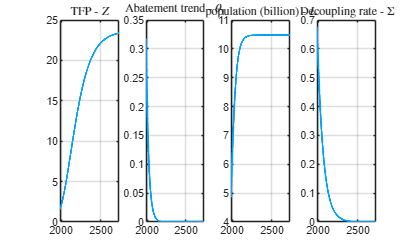

nx = 1;ny = 4;varnames=char('Z','THETA1','L','SIG');
nn=size(varnames,1);
figure('Name','Figure 1: Exogenous Variables');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	plotds(varnames(i1,:),deterministic_simuls,'Color',[3, 161, 252]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(deterministic_simuls,1))
	grid on
	title([ M_.endo_names_long{idx} ' - $' M_.endo_names_tex{idx} '$'],'Interpreter','latex')
end

### B. Plot of the endogenous variables

We now examine how key endogenous variables evolve along the deterministic transition path under the Business-As-Usual (BAU) scenario.

The variables plotted below include output, consumption, labor, damages, carbon tax in USD, emissions, temperature, and the carbon stock.

These trajectories correspond to the model's equilibrium response when no shock occurs and when climate policy follows the baseline exogenous path encoded in `exo_init_ts`.

The plot focuses on the period 2000–2100 for readability.

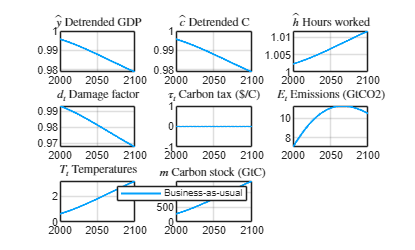

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 2: Endogenous Variables Business as usual');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	plotds(varnames(i1,:),deterministic_simuls,'Color',[3, 161, 252]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(deterministic_simuls,1))
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([2000 2100])
end
legend('Business-as-usual')